## 4. Distance transform (page 132) 

### a) Create an obstacle map that contains a maze and solve it using distance transform.

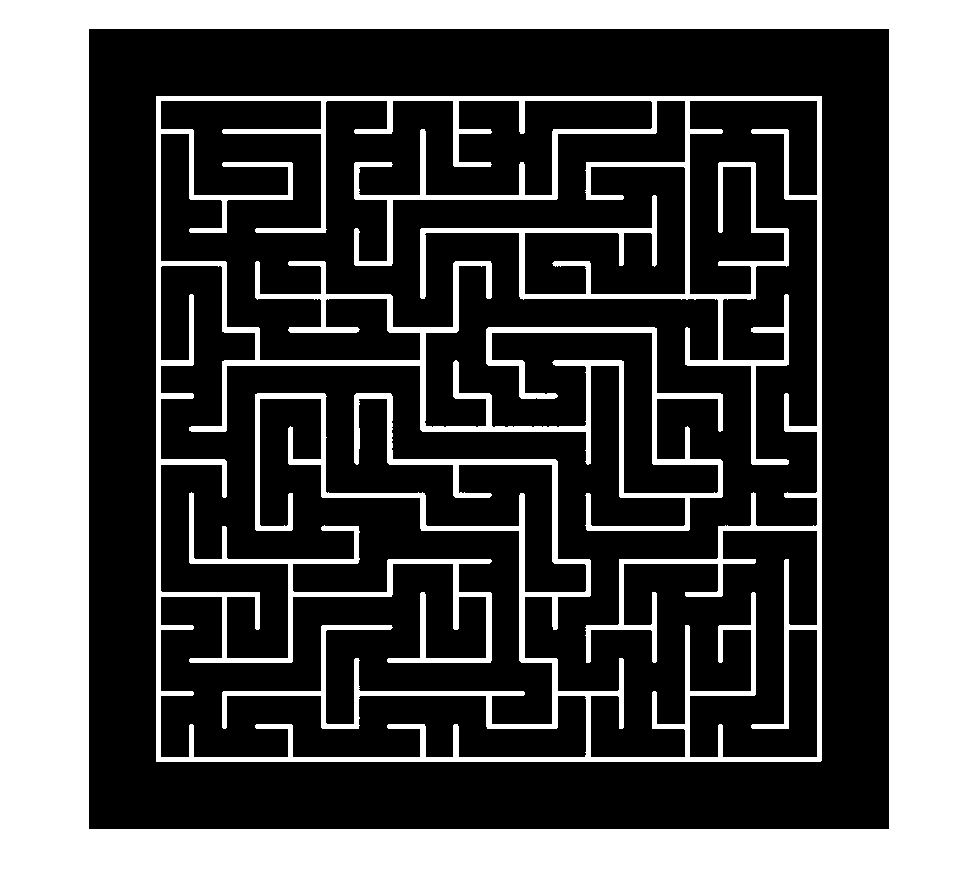

clear
close all
clf

% Read the maze
map = imread('maze.jpg');  
% Binarize the image
map = rgb2gray(map);
% Establish the walls
map = (map < 100);
% Remove the exits/entring of the maze
map(68:72, 68:733) = 1;
map(68:733, 68:72) = 1;
imshow(map)

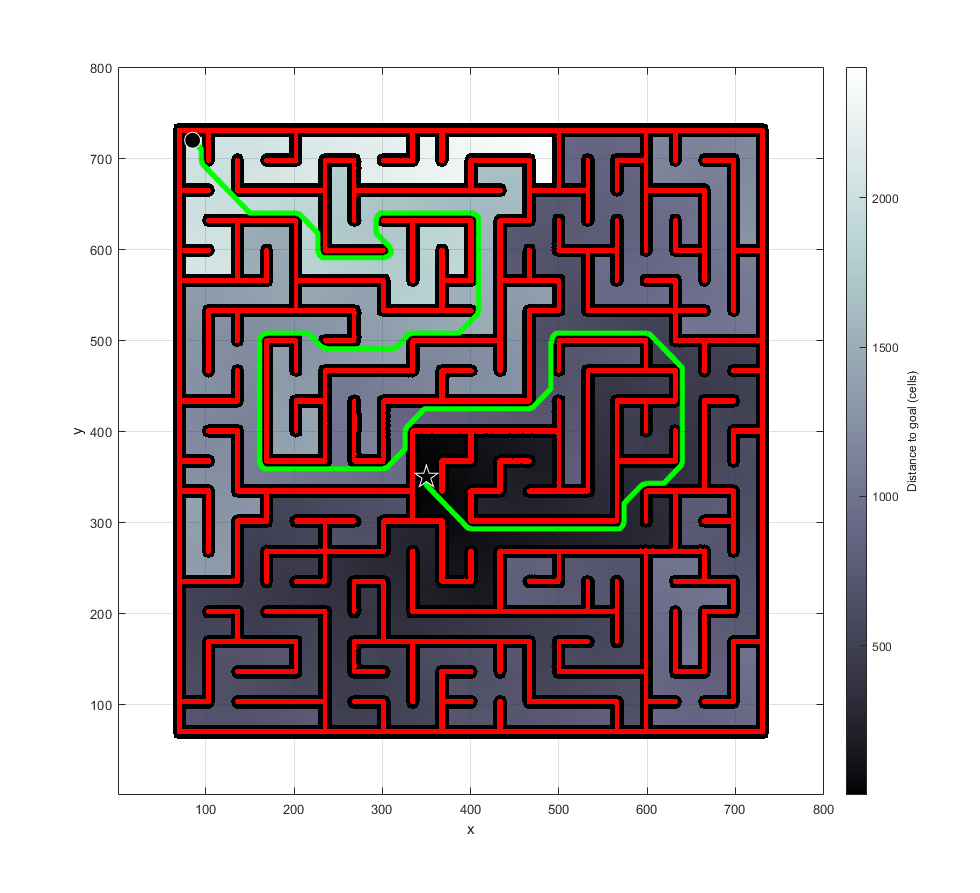

dx = DXform(map, 'inflate', 5);
start = [85, 720];
goal = [350, 350];
dx.plan(goal);
p = dx.query(start); 
dx.plot(p)
hold off

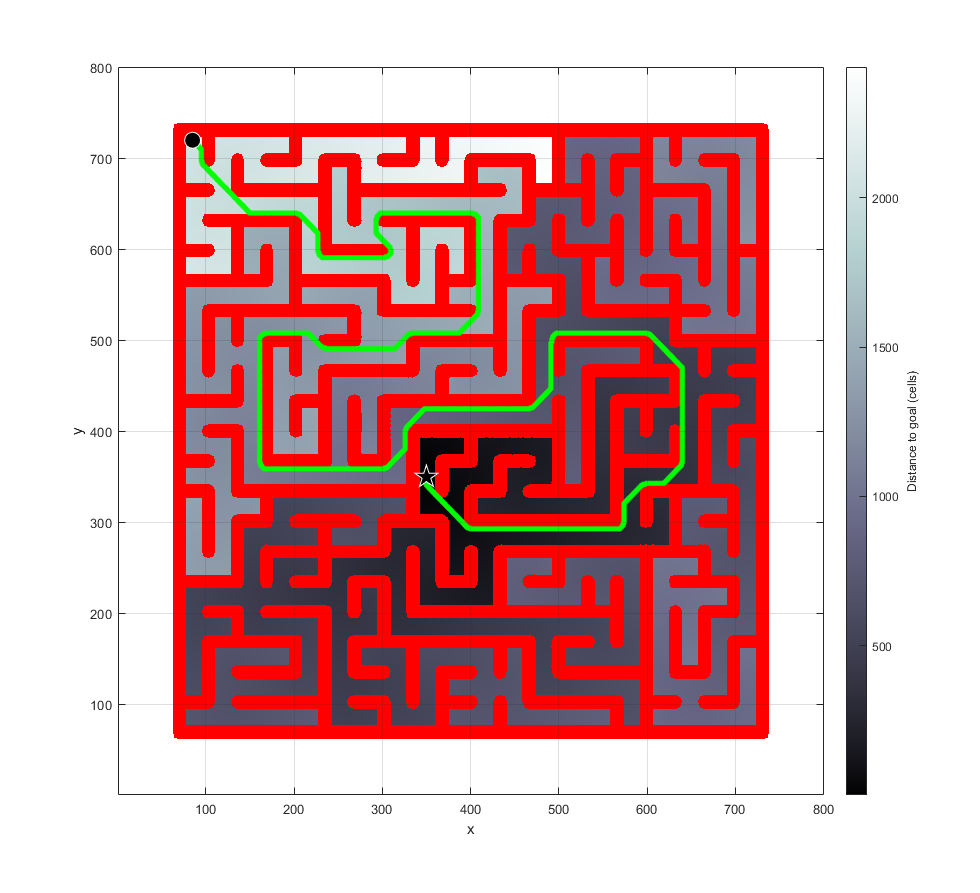

dx.plot(p, 'inflated')

## 5. D∗ planner (page 134) 

### a) Add a low cost region to the living room. Can you make the robot prefer to take  this route to the kitchen? 

clear
close all
clf

load house
ds = Dstar(house);
c = ds.costmap(); 
ds.plan(place.kitchen); 

245184 iterations


p = ds.query(place.br3);
ds.modify_cost( [200, 269; 113, 205], 0);
ds.plan();

322193 iterations


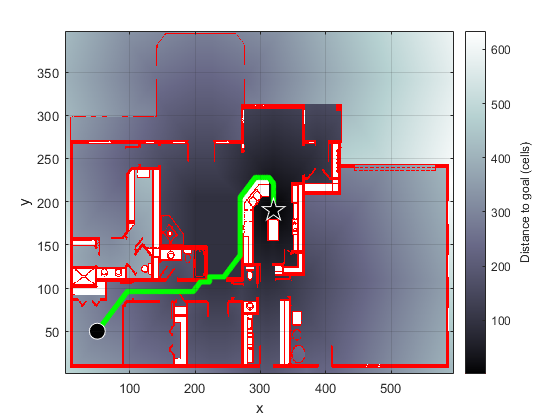

p = ds.query(place.br3);
ds.plot(p)
hold off

### b) Block additional doorways to challenge the robot.

To begin with, we block the living and kitchen doors.

close all
figure
hold on

ds = Dstar(house);
c = ds.costmap(); 
ds.plan(place.kitchen);

245184 iterations


ds.query(place.br3);
ds.modify_cost( [222, 247; 108, 112], 2000);       % Living room door
ds.modify_cost( [300,325; 115,125], 2000);         % Kitchen door
ds.plan();

179526 iterations


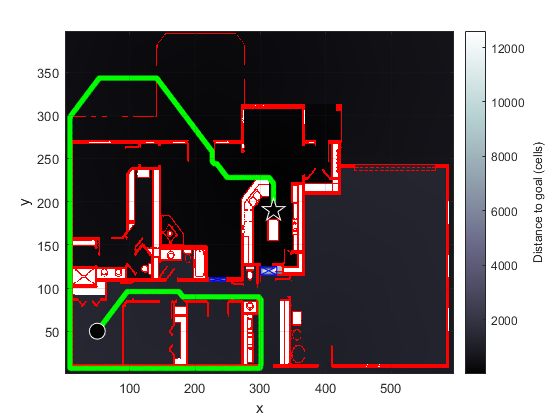

p1 = ds.query(place.br3);
door1 = doorPlot(222, 247, 108, 112);
door2 = doorPlot(300, 325, 115, 125);
ds.plot(p1)
hold on
plot(door1(:, 1), door1(:, 2), 'b')
plot(door2(:, 1), door2(:, 2), 'b')
hold off

We also block the door that the algorithm use to achieve the goal to see what it does now.

close all
figure
hold on

ds.modify_cost( [300, 318; 8, 11], 2000);
ds.plan();

68265 iterations


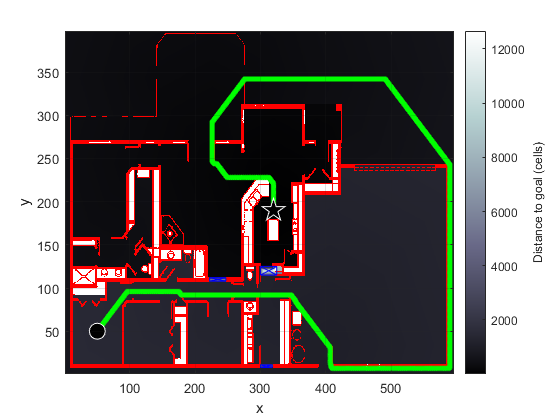


p2 = ds.query(place.br3);
ds.plot(p2)
hold on
door3 = doorPlot(300, 318, 8, 11);
plot(door1(:, 1), door1(:, 2), 'b')
plot(door2(:, 1), door2(:, 2), 'b')
plot(door3(:, 1), door3(:, 2), 'b')

As a last test, we close all the doors to see which route it takes.

close all
figure
hold on

ds.modify_cost( [390, 408; 9, 12], 2000);
ds.plan();

294831 iterations


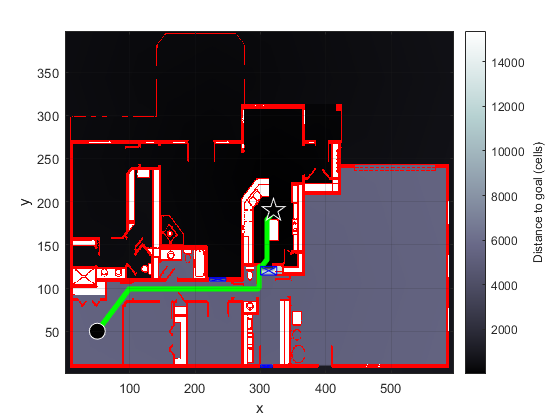


p3 = ds.query(place.br3);
ds.plot(p3)
hold on
door4 = doorPlot(390, 408, 9, 12);
plot(door1(:, 1), door1(:, 2), 'b')
plot(door2(:, 1), door2(:, 2), 'b')
plot(door3(:, 1), door3(:, 2), 'b')

We can observe that it takes the initial path, that is because as all the doors have an extra cost (all of this doors have the same cost), so it doesn't care which one we choose.

## 6. PRM planner (page 138) 

### a) Run the PRM planner 100 times and gather statistics on the resulting path length.

clear
close all
clf

load house
prm = PRM(house);

count = 1;
for i = 1:100
    prm.plan();
    
    try
        p = prm.query(place.br3, place.kitchen);
        length(count) = height(p);
        count = count + 1;
    catch
        
    end
end

max(length)

ans = 11

min(length)

ans = 2

mean(length)

ans = 2.8043

var(length)

ans = 5.4778

cov(length)

ans = 5.4778

std(length)

ans = 2.3405

### b) Vary the value of the distance threshold parameter and observe the effect.

The default treshold is 178.8, let's try with 300.

prm = PRM(house, 'distthresh', 300);
count = 1;
for i = 1:100
    prm.plan();
    
    try
        p = prm.query(place.br3, place.kitchen);
        length(count) = height(p);
        count = count + 1;
    catch
        
    end
end

max(length)

ans = 12

min(length)

ans = 2

mean(length)

ans = 2.8478

var(length)

ans = 5.8227

cov(length)

ans = 5.8227

std(length)

ans = 2.4130

Notice that all the statistics value increase a bit due to the treshold icreases as well, but not in the same ratio.

Second try with 75

prm = PRM(house, 'distthresh', 75);
count = 1;
for i = 1:100
    prm.plan();
    
    try
        p = prm.query(place.br3, place.kitchen);
        length(count) = height(p);
        count = count + 1;
    catch
        
    end
end

max(length)

ans = 13

min(length)

ans = 2

mean(length)

ans = 2.1170

var(length)

ans = 1.2872

cov(length)

ans = 1.2872

std(length)

ans = 1.1346

In this case, the length always is the same, so the variance, covariance and standard deviation are 0.

## 7. Lattice planner (page 140) 

### a) How many iterations are required to completely fill the region of interest shown in Fig. 5.13c? 

If the area of interest ranges from -1 to 3 on the x- and from -3 to 3 on the y-axis, then it is enough to  4 iterations to fill the region. But if what we want is to fill more possible paths as shown in the same figure, then we need 8 iterations.

clear
close all
clf

lp = Lattice();
lp.plan('iterations', 3)

38 nodes created


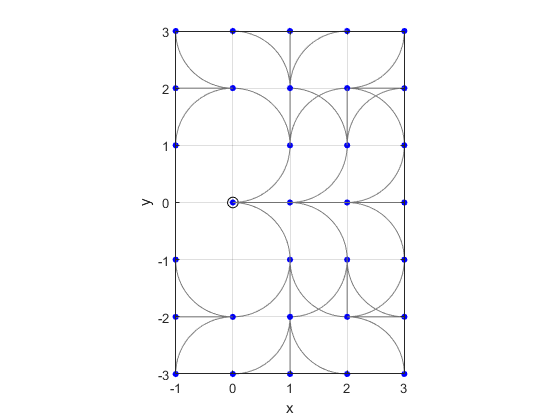

lp.plot();
xlim([-1, 3])
ylim([-3, 3])

lp.plan('iterations', 4)

97 nodes created


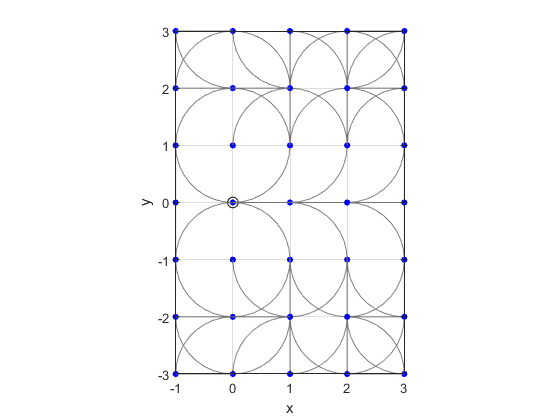

lp.plot();
xlim([-1, 3])
ylim([-3, 3])

### b) How does the number of nodes and the spatial extent of the lattice increase with  the number of iterations? 

As we can see below, every iteration the the range of x and y increases by 2, in other words every 1 iteration the distance between the minimum and maximum point of x- and y-axis increases by 2.

lp = Lattice();

for i = 1:10
    lp.plan('iterations', i)
    max(lp.graph.vertexlist(1, :)) - min(lp.graph.vertexlist(1, :))
    max(lp.graph.vertexlist(2, :)) - min(lp.graph.vertexlist(2, :))
    max(lp.graph.vertexlist(3, :)) - min(lp.graph.vertexlist(3, :))
end

4 nodes created


ans = 1

ans = 2

ans = 3

13 nodes created


ans = 2

ans = 4

ans = 3

38 nodes created


ans = 4

ans = 6

ans = 3

97 nodes created


ans = 6.0000

ans = 8

ans = 3

209 nodes created


ans = 8

ans = 10

ans = 3

372 nodes created


ans = 10

ans = 12

ans = 3

566 nodes created


ans = 12

ans = 14

ans = 3

780 nodes created


ans = 14

ans = 16

ans = 3

1020 nodes created


ans = 16

ans = 18

ans = 3

1292 nodes created


ans = 18

ans = 20

ans = 3

### c) Given a car with a wheelbase of 4.5 m and maximum steering angles of ±30 deg  what is the smallest possible grid size? 

13.5 m

### d) Redo Fig. 5.15b to achieve a path that uses only right hand turns. 

lp = Lattice()

 
lp = 
Lattice navigation class:
  occupancy grid: 0x0    
  grid spacing: 1        
  costs [1,1,1]          
  iterations Inf         
 Graph:                  
  3 dimensions           
  0 vertices             
  0 edges                
  0 components           


lp.plan('iterations', 8, 'cost', [1 10 10]);       % Cost for straight, left, right (default [1,1,1])

780 nodes created


lp.query( [1 2 pi/2], [2 -2 0] );

A* path cost 35


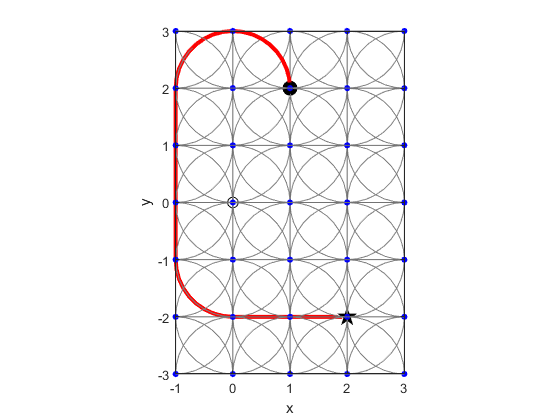

lp.plot();
xlim([-1, 3])
ylim([-3, 3])

### e) Compute curvature as a function of path length for a path through the lattice  such as the one shown in Fig. 5.15a.

To compute the curvature I will divide the number of turns by the number of sections travelled.

clear
close all
clf

lp = Lattice();
lp.plan('iterations', 8);       % Cost for straight, left, right (default [1,1,1])

780 nodes created


lp.query( [1 2 pi/2], [2 -2 0] );

A* path cost 6


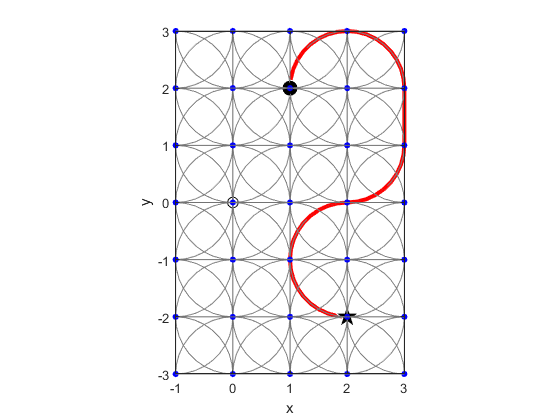

lp.plot();
xlim([-1, 3])
ylim([-3, 3])

% obtain all the nodes of the path
pathNodes = lp.vpath();

% Count the number of turns
turns = 0;
for i = 2:width(pathNodes)
    node = pathNodes(i);
    prevNode = pathNodes(i-1);
    x = round(lp.graph.vertexlist(1, node));
    y = round(lp.graph.vertexlist(2, node));
    
    prevx = round(lp.graph.vertexlist(1, prevNode));
    prevy = round(lp.graph.vertexlist(2, prevNode));
    
    if (prevy ~= y && prevx ~= x)
        turns = turns + 1;
    end
end
curvature = turns / (width(pathNodes) - 1)

curvature = 0.8333

## 8. RRT planner (page 144) 

### a) Find a path to implement a 3-point turn. 

clear
close all
clf

car = Bicycle('steermax', 0.5);
rrt = RRT(car, 'npoints', 1000)

 
rrt = 
RRT navigation class:                                   
  occupancy grid: 0x0                                   
  region: X -5.000000 : 5.000000; Y -5.000000 : 5.000000
  sim time: 0.500000                                    
  speed: 1.000000                                       
 Graph:                                                 
  3 dimensions                                          
  0 vertices                                            
  0 edges                                               
  0 components                                          
Bicycle object                                          
  L=1, steer.max=0.5, accel.max=Inf                     
  Superclass: Vehicle                                   
    max speed=1, dT=0.1, nhist=0                        
    configuration: x=0, y=0, theta=0                    


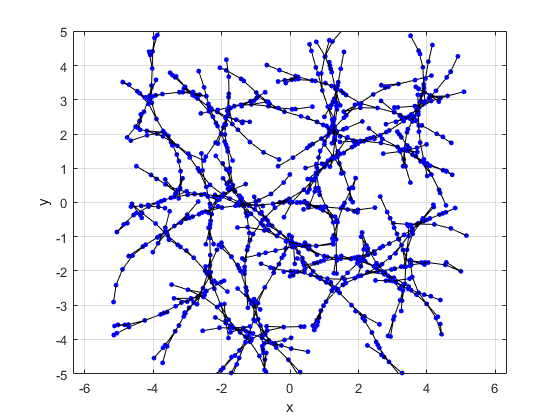

rrt.plan();
rrt.plot();

p = rrt.query([0 0 0], [0 -1 pi]);

A* path cost 14


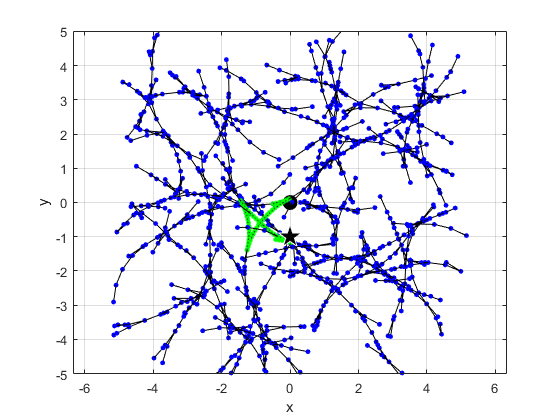

rrt.plot(p)

### b) Experiment with RRT parameters such as the number of points, the vehicle steering angle limits, and the path integration time. 

clear
close all
clf

car = Bicycle('steermax', pi);
rrt = RRT(car, 'npoints', 100, [-3, 3], 'simtime', 4)

 
rrt = 
RRT navigation class:                                   
  occupancy grid: 0x0                                   
  region: X -5.000000 : 5.000000; Y -5.000000 : 5.000000
  sim time: 4.000000                                    
  speed: 1.000000                                       
 Graph:                                                 
  3 dimensions                                          
  0 vertices                                            
  0 edges                                               
  0 components                                          
Bicycle object                                          
  L=1, steer.max=3.14159, accel.max=Inf                 
  Superclass: Vehicle                                   
    max speed=1, dT=0.1, nhist=0                        
    configuration: x=0, y=0, theta=0                    


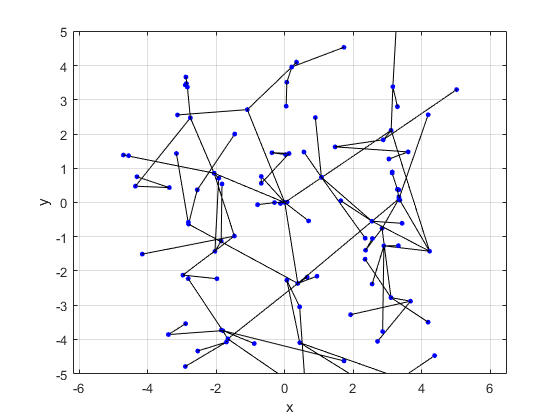

rrt.plan();
rrt.plot();

car = Bicycle('steermax', pi/6);
rrt = RRT(car, 'npoints', 100, 'simtime', 4)

 
rrt = 
RRT navigation class:                                   
  occupancy grid: 0x0                                   
  region: X -5.000000 : 5.000000; Y -5.000000 : 5.000000
  sim time: 4.000000                                    
  speed: 1.000000                                       
 Graph:                                                 
  3 dimensions                                          
  0 vertices                                            
  0 edges                                               
  0 components                                          
Bicycle object                                          
  L=1, steer.max=0.523599, accel.max=Inf                
  Superclass: Vehicle                                   
    max speed=1, dT=0.1, nhist=0                        
    configuration: x=0, y=0, theta=0                    


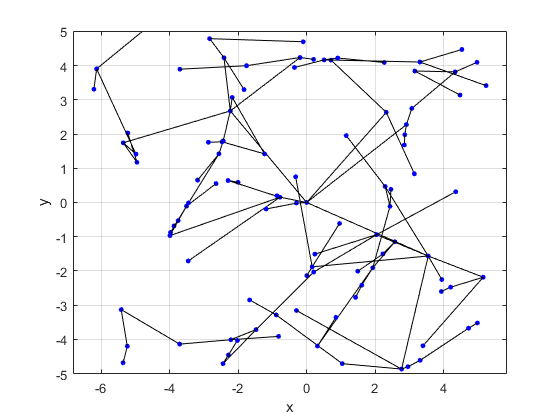

rrt.plan();
rrt.plot();

car = Bicycle('steermax', pi/6);
rrt = RRT(car, 'npoints', 100, 'simtime', 1)

 
rrt = 
RRT navigation class:                                   
  occupancy grid: 0x0                                   
  region: X -5.000000 : 5.000000; Y -5.000000 : 5.000000
  sim time: 1.000000                                    
  speed: 1.000000                                       
 Graph:                                                 
  3 dimensions                                          
  0 vertices                                            
  0 edges                                               
  0 components                                          
Bicycle object                                          
  L=1, steer.max=0.523599, accel.max=Inf                
  Superclass: Vehicle                                   
    max speed=1, dT=0.1, nhist=0                        
    configuration: x=0, y=0, theta=0                    


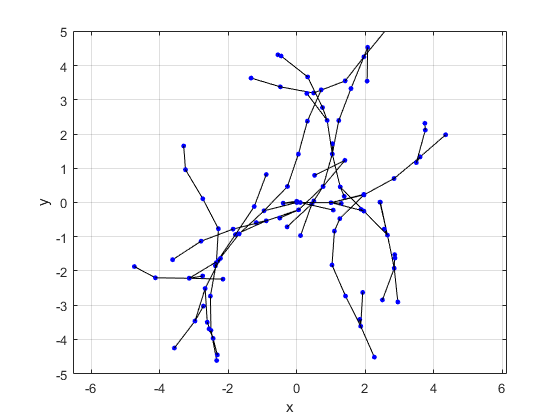

rrt.plan();
rrt.plot();

### c) Additional information in the node of each graph holds the control input that  was computed to reach the node. Plot the steering angle and velocity sequence  required to move from start to goal pose. 

p = rrt.query([0 0 0], [4 2 0]);

A* path cost 5


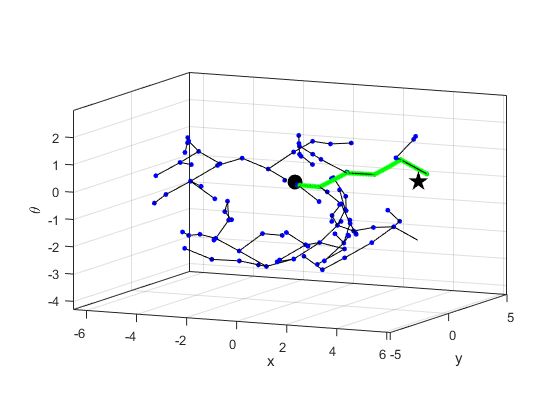

rrt.plot(p)

for i = 2:height(p)
    x = p(i, 1);
    y = p(i, 2);
    z = p(i, 3);
    for j = 1:width(rrt.graph.vertexlist)
        x2 = rrt.graph.vertexlist(1, j);
        y2 = rrt.graph.vertexlist(2, j);
        z2 = rrt.graph.vertexlist(3, j);
        
        if x2 == x && y2 == y && z2 == z
            dataNode = rrt.graph.vertexdata{1, j};
            fprintf('Node %d', j);
            steering_angle = dataNode.steer
            velocity = dataNode.vel
        end
    end
end

Node 2

steering_angle = -0.0112

velocity = 1

Node 5

steering_angle = 0.4960

velocity = 1

Node 17

steering_angle = -0.0679

velocity = 1

Node 31

steering_angle = 0.4705

velocity = 1

Node 74

steering_angle = -0.5155

velocity = 1

### d) Add a local planner to move from initial pose to the closest vertex, and from the  final vertex to the goal pose.

count = 1;
for i = 2:height(p)
    x = p(i, 1);
    y = p(i, 2);
    z = p(i, 3);
    for j = 1:width(rrt.graph.vertexlist)
        x2 = rrt.graph.vertexlist(1, j);
        y2 = rrt.graph.vertexlist(2, j);
        z2 = rrt.graph.vertexlist(3, j);
        
        if x2 == x && y2 == y && z2 == z
            path(count) = j;
            count = count + 1;
        end
    end
end

origin_vertex = path(1)

origin_vertex = 2

network_navigation = path(2:end-1)

network_navigation =      5    17    31


vertex_goal = path(end)

vertex_goal = 74

function door = doorPlot(firstX, lastX, firstY, lastY)
numCols = lastX - firstX + 1;
numRows = lastY - firstY + 1;
door = [(firstX:lastX)', zeros(numCols, 1) + firstY; (firstX:lastX)', zeros(numCols, 1) + lastY; zeros(numRows, 1) + firstX, (firstY:lastY)'; zeros(numRows, 1) + lastX, (firstY:lastY)'];
end